load("lab3_exp3_data.mat")

Vin = Vin_e3

Vin =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


Vout = Vout_e3

Vout =     0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0017    0.0025    0.0073    0.0243    0.0532    0.0894    0.1296    0.1720    0.2161    0.2612    0.3067    0.3529    0.3996    0.4468    0.4941    0.5416    0.5869    0.6348    0.6828    0.7310    0.7794    0.8280    0.8765    0.9249    0.9736    1.0224    1.0713    1.1202    1.1693    1.2183    1.2672    1.3162    1.3654    1.4144    1.4636    1.5129    1.5622    1.6113    1.6606    1.7101    1.7594



plot(Vin, Vout, ".", "DisplayName", "Experimental Plot")
f = polyfit(Vin(12:end), Vout(12:end), 1)

f =     0.9802   -0.6296


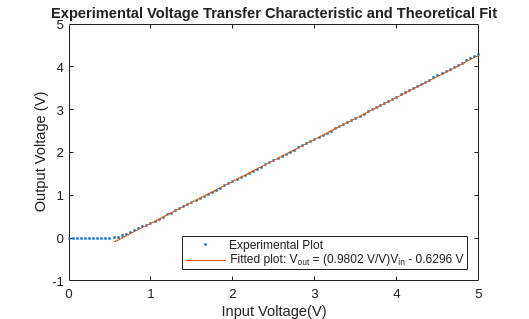

hold on
plot(Vin(12:end), f(1).*Vin(12:end) + f(2), "DisplayName", "Fitted plot: V_{out} = (0.9802 V/V)V_{in} - 0.6296 V")
xlabel("Input Voltage(V)")
ylabel("Output Voltage (V)")
title("Experimental Voltage Transfer Characteristic and Theoretical Fit")
xlim([0 5])
legend(Location='southeast')
hold off

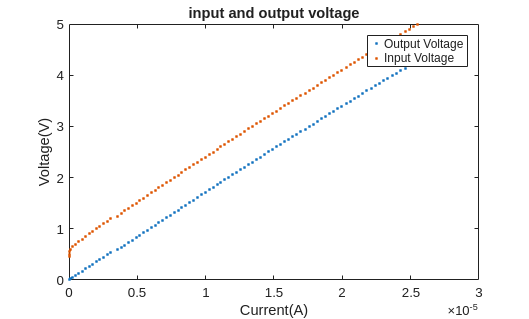


plot(Iin_e3(10:end), Vout(10:end),".",  "DisplayName" ,"Output Voltage")
hold on
plot(Iin_e3(10:end), Vin(10:end),".",  "DisplayName" ,"Input Voltage")
title("input and output voltage")
xlabel("Current(A)")
ylabel("Voltage(V)")
legend()
hold off


voltage_diff = sum(Vout(10:end) - Vin(10:end))/length(Vin(10:end))

voltage_diff = -0.6799